Finding Gradient at a point

syms x y z real
f=80/(1+x^2+2*y^2+3*z^2)

$$f = \frac{80}{x^{2}+2\,y^{2}+3\,z^{2}+1}$$

p=sym([1 1 -2])

$$p = \left(\begin{array}{ccc} 1 & 1 & -2 \end{array}\right)$$

grad_f=gradient(f, [x y z])'

$$grad\_f = \left(\begin{array}{ccc} -\frac{160\,x}{{\left(x^{2}+2\,y^{2}+3\,z^{2}+1\right)}^{2}} & -\frac{320\,y}{{\left(x^{2}+2\,y^{2}+3\,z^{2}+1\right)}^{2}} & -\frac{480\,z}{{\left(x^{2}+2\,y^{2}+3\,z^{2}+1\right)}^{2}} \end{array}\right)$$

grad_f_p= subs(grad_f, [x y z], p)

$$grad\_f\_p = \left(\begin{array}{ccc} -\frac{5}{8} & -\frac{5}{4} & \frac{15}{4} \end{array}\right)$$

Plot the gradient field:

f = $\frac{1}{2}\;\left(x^2 -y^2 \right)$

syms x y
f=(1/2)*(x^2-y^2)

$$f = \frac{x^{2}}{2}-\frac{y^{2}}{2}$$

gradf=gradient(f, [x y])'

$$gradf = \left(\begin{array}{cc} \bar{x} & -\bar{y} \end{array}\right)$$

syms x y 
f = (1 / 2) * (x^2 - y^2)

$$f = \frac{x^{2}}{2}-\frac{y^{2}}{2}$$

grad_f = gradient(f, [x  ,y])'

$$grad\_f = \left(\begin{array}{cc} \bar{x} & -\bar{y} \end{array}\right)$$

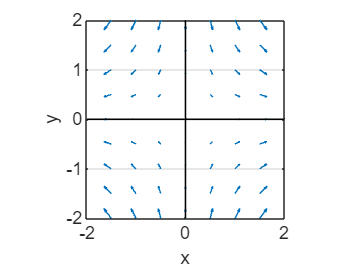

[x, y]=meshgrid([-2:0.5:2, -2:0.5:2]);
u = x; v = -y;
figure
quiver(x, y, u, v)
hold on
grid on
plot([ 0 0], [-3 3], 'k')
plot([-3 3], [0 0], 'k')
axis equal 
axis([-2 2 -2 2]), xlabel('x')
ylabel('y')

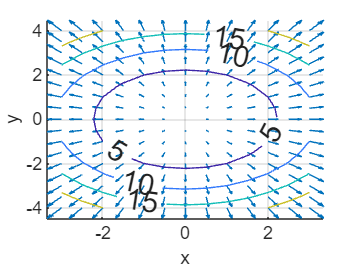

[x, y] = meshgrid(-3 : 0.5 : 3, -4:0.5:4);
f= x.^2 + y.^2;
figure
hold on
grid on
[u,v] = gradient(f);
quiver(x, y, u, v )
[c, n] = contour(x, y, f);
clabel(c, n, 'Fontsize', 15)
xlabel('x')
ylabel('y')

syms x y z real
P = sym([3 4  5])

$$P = \left(\begin{array}{ccc} 3 & 4 & 5 \end{array}\right)$$

v  = 5*x^2 - 3*x*y + x*y*z

$$v = 5\,x^{2}-3\,x\,y+x\,y\,z$$

grad_v  = gradient(v, [x y z])'

$$grad\_v = \left(\begin{array}{ccc} 10\,x-3\,y+y\,z & x\,z-3\,x & x\,y \end{array}\right)$$

grad_pt = subs(grad_v, [x y z], P)

$$grad\_pt = \left(\begin{array}{ccc} 38 & 6 & 12 \end{array}\right)$$

a = [1 1 -1]%given direction 

a =      1     1    -1


n = a / norm(a) %unit vector in given direction

n =     0.5774    0.5774   -0.5774


DD = dot(grad_pt, n)

$$DD = \frac{32\,\sqrt{3}}{3}$$

direction_of_rapid_change =grad_pt

$$direction\_of\_rapid\_change = \left(\begin{array}{ccc} 38 & 6 & 12 \end{array}\right)$$

max_rate_of_change = norm(grad_pt)

$$max\_rate\_of\_change = \sqrt{1624}$$